# CX 4803 - Assignment 5 - Quill Healey

## Question 1

Let us first consider how we should expect our classifier to make decisions. Note that this problem falls under the umbrella of decision theory as the inference of the class-conditional densities, as well as class priors, has been done for us. Now, given some input vector $\mathbf{x}$, our goal is to decide which of the two clases to assign the data. More specifically, we are interested in the probabilities of the two classes given $\mathbf{x}$, which can be written mathematically as $p(C_k|\mathbf{x})$. Using Bayes' theorem, these probabilties can be expressed in the form

$p(C_k|\mathbf{x}) = \frac{p(\mathbf{x}|C_k)p(C_k)}{p(\mathbf{x})}$, $k \in \{1, 2\}$.

Given that our aim is to minimize the chance of assigning $\mathbf{x}$ to the wrong class, then intuitively we will choose the class having the higher posterior probability. Finding the equation of the discriminant(s), therefore, is just a matter of determing which vectors $\mathbf{x}$ result in equal posteriors: $p(C_1|\mathbf{x}) = p(C_2|\mathbf{x})$. We can derive these results algebraically by setting the posteriors equal to each other, expressing the probabilities according to Bayes' Theorem (above), and then substituting in the values provided by the prompt.


$$\begin{array}{rcl}
p(C_1|\mathbf{x}) &=& p(C_2|\mathbf{x})\\
\frac{p(\mathbf{x}|C_1)p(C_1)}{p(\mathbf{x})} &=& \frac{p(\mathbf{x}|C_2)p(C_2)}{p(\mathbf{x})} \\
\text{The} \ p(\mathbf{x}) \ \text{terms cancel, as do} \ &p(C_1)& \ \text{and} \ p(C_2) \ \text{(as stated by problem description)}\\
\Rightarrow p(\mathbf{x}|C_1) &=& p(\mathbf{x}|C_2)\\
\text{Substitute in} &\text{the}& \text{class-conditional densities:}\\
N\left(\mathbf{x}|\pmatrix{0 \cr 2}, \pmatrix{2 & 0 \cr 0 & 1}\right) &=&N\left(\mathbf{x}|\pmatrix{2 \cr 0}, \pmatrix{1 & 0 \cr 0 & 2}\right)\\
\text{Preliminary calculations:}\\
D &=& 2, \ \\
\left|\pmatrix{2 & 0 \cr 0 & 1}\right| &=& \left|\pmatrix{1 & 0 \cr 0 & 2}\right| = 2\\
\pmatrix{2 & 0 \cr 0 & 1}^{-1} &=& \frac{1}{2} \pmatrix{1 & 0 \cr 0 & 2}\\
\pmatrix{1 & 0 \cr 0 & 2}^{-1} &=& \frac{1}{2}\pmatrix{2 & 0 \cr 0 & 1}\\
\text{Rewrite the probabilities according to the Gaussian's}  &\text{PDF:}& N(\mathbf{x}|\mu, \Sigma) = \frac{1}{(2\pi)^{D/2}} \frac{1}{|\Sigma|^{1/2}}exp\left\{-\frac{1}{2}(\mathbf{x} - \mathbf{\mu})^T\Sigma^{-1}(\mathbf{x} - \mathbf{\mu})\right\}\\
\frac{1}{(2\pi)^{2/2}} \frac{1}{2^{1/2}}exp\left\{-\frac{1}{2}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)^T \frac{1}{2} \pmatrix{1 & 0 \cr 0 & 2}^{-1}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)\right\} &=&
\frac{1}{(2\pi)^{2/2}} \frac{1}{2^{1/2}}exp\left\{-\frac{1}{2}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)^T\frac{1}{2}\pmatrix{2 & 0 \cr 0 & 1}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)\right\}\\
exp\left\{-\frac{1}{2}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)^T\ \frac{1}{2} \pmatrix{1 & 0 \cr 0 & 2}^{-1}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)\right\} &=&
exp\left\{-\frac{1}{2}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)^T\frac{1}{2}\pmatrix{2 & 0 \cr 0 & 1}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)\right\}\\
\text{Take the natural} &\text{log}& \text{of the equation}\\
{-\frac{1}{2}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)^T \frac{1}{2} \pmatrix{1 & 0 \cr 0 & 2}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right) &=&
-\frac{1}{2}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)^T\frac{1}{2}\pmatrix{2 & 0 \cr 0 & 1}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)\\
\left(\mathbf{x} - \pmatrix{0 \cr 2}\right)^T \pmatrix{1 & 0 \cr 0 & 2}\left(\mathbf{x} - \pmatrix{0 \cr 2}\right) &=&
\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)^T\pmatrix{2 & 0 \cr 0 & 1}\left(\mathbf{x} - \pmatrix{2 \cr 0}\right)\\
\text{Let} \ \mathbf{x} &=&  \pmatrix{x_1 & x_2}^T\\
\pmatrix{x_1 & x_2 - 2} \pmatrix{x_1 \cr 2x_2 - 4} &=& \pmatrix{x_1 - 2 & x_2} \pmatrix{2x_1 - 4 \cr x_2}\\
x_1^2 + (x_2-2)(2x_2-4) &=& (x_1 - 2)(2x_1-4) + x_2^2\\
x_1^2 + 2x_2^2 - 4x_2 - 4x_2 + 8 &=& 2x_1^2 - 4x_1 - 4x_1 + 8 + x_2^2\\
x_2^2 - 8x_2 &=& x_1^2 - 8x_1\\
x_2^2 - 8x_2 + 16 &=& x_1^2 - 8x_1 + 16\\
(x_2-4)^2 &=& (x_1 - 4)^2\\
x_2 - 4 = x_1 - 4 &or& x_2 - 4 = -x_1 + 4\\
\therefore \  x_2 = x_1 &or& x_2 = -x_1 + 8
\end{array}\\
 $$


Given an input vector in the $x_1x_2$ plane, the decision regions are given by the discriminants: $x_2 = x_1$ and $x_2 = 8 - x_1$.

## Question 2

% Load Given data
x1 = [0.8147
0.9058
0.1270
0.9134
0.6324
0.0975
0.2785
0.5469
0.9575
0.9649
1.5060
0.8318
1.0769
0.8462
0.8971
1.6235
1.4948
1.1171
1.7502
0.8344];

x2 = [0.1576
0.9706
0.9572
0.4854
0.8003
0.1419
0.4218
0.9157
0.7922
0.9595
1.2387
1.1816
1.5655
1.5952
0.9869
1.2898
1.2456
1.4463
1.5094
1.5547];

x3 = [0.6557
0.0357
0.8491
0.9340
0.6787
0.7577
0.7431
0.3922
0.6555
0.1712
1.0760
1.4797
1.4551
0.9626
0.9190
1.2984
1.7597
1.1404
1.3853
1.0238];

y = [0
0
0
0
0
0
0
0
0
0
1
1
1
1
1
1
1
1
1
1];
x = [x1 x2 x3];

% perform minimization of the negative log likelihood
% negative log likelihood functions defined below -> same fundamentals as
% class code
fun = @(w) neglog_likelihood(w, x, y);
w = fminunc(fun, [0 0 0 0]');


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% computed weight values for the linear discriminant
w

w =  -162.9663
   40.5115
   71.9365
   74.3494


s1 = w(1) + w(2)*0.9 + w(3)*1 + w(4)*0.9; % discriminant
prob = 1 / (1 + exp(-s1));
prob

prob = 1.0000

Having computed our discriminant to be $s = -162.9663 + 40.5115*x_1 + 71.9365*x_2 + 74.3494*x_3$, recall that $p(C_1|\mathbf{x}) = \frac{1}{1 + exp(-s)}$. Therefore, substituting $\pmatrix{0.9 & 1.0 & 0.9}^T$ for $\pmatrix{x_1 & x_2 & x_3}^T$ in the equation for the discriminant, and subsequently plugging $s$ into our posterior probability, we find that there is a 100% probability that the point $\pmatrix{0.9 & 1.0 & 0.9}^T \in C_0$ and a subsequent 0% probability that it belongs to class 2 (I'd guess that matlab is rounding up, probabilities closer to 0.999... and 0.000...1 are theoretically more valid). 

(Now I perform quadratic regression to verify my result).

fun2 = @(w) neglog_likelihood_quad(w, x, y);
w = fminunc(fun2, zeros(10, 1));


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w

w =   -46.6930
  -12.9069
   -9.0190
   -7.3187
    4.9340
   14.4930
   19.2493
   25.2094
   17.5527
   15.0392


s2 = w(1) + w(2)*0.9 + w(3)*1 + w(4)*0.9 + w(5)*.81 + w(6)*.9 + w(7)*.81 + w(8)*.9 + w(9)*1 + w(10)*.81;
1 / (1 + exp(-s2))

ans = 1.0000

## Question 3

Before generating the desired figure let's understand its mathematical mechanics.

Suppose we are given a $N \times 2$ matrix :

$\mathbf{X} = \pmatrix{x_1^1 & x_2^1 \cr x_1^2 & x_2^2 
\cr \vdots & \vdots \cr x_1^N & x_2^N} = \pmatrix{\mathbf{x}_1 \cr \mathbf{x}_2 \cr \vdots \cr \mathbf{x}_N}$,

where each row represents a point in the $x_1x_2$ input space belonging to one of two classes: $\{Blue, Red\} = \{0, 1\}$. For convenience, we will represent each of these points with a vector: $\mathbf{x}_n = \pmatrix{x_1^n & x_2^n}, \ n = 1, \ldots, N$. 

Now, as this is a classification problem, we hope to develop some system that when given a new point $\mathbf{x}_0 = \pmatrix{x_1^0, x_2^0}$, determines whether $\mathbf{x}_0 \in Red \ \text{or} \ \mathbf{x}_0 \in Blue$. Suppose that having settled upon a probabilistic discriminative model, namely logistic regression with a linear discriminant, to model the system we now plot our data in the $x_1x_2$ plane only to see that there is no clear linear discriminant that separates our decision regions. While we could change modeling approaches, there is a solution to our problem: transforming the feature space to create linearly separable decision regions. 

While usually a transformation of this nature is one that brings our input data to a higher dimension, Bishop oddly chooses an example where the transformed feature space remains two dimensional. Namely, he uses two Gaussian basis functions. We will explain the figure's transformation technique now.

Recall that a Gaussian basis function takes the form:

$\phi(\mathbf{x}) = exp\left\{-\frac{||\mathbf{x} - \mathbf{\mu}||_2^2}{2s^2}\right\}$.

Our transformed feature space can be written as follows:

$\Phi = \pmatrix{\phi_1(\mathbf{x_1}) & \phi_2(\mathbf{x_1}) \cr \phi_1(\mathbf{x_2}) & \phi_2(\mathbf{x_2}) \cr \vdots & \vdots \cr \phi_1(\mathbf{x_N}) & \phi_2(\mathbf{x_N})}$,

where both basis functions have $s = 0.9$ and are centered at $\pmatrix{-1 & -1}^T$ and $\pmatrix{0 & 0}^T$ respectively. Note that our feature matrix is once again $N \times 2$.

With that understanding we will now build the figure.

% Generating the data points for each class

% Number of data points for each class
N = 100;
% Covariance Matrices and corresponding Lower Cholesky factors
sigma = diag(repelem(0.02, 100));
sigma2 = diag(repelem(0.02, 50));
L = chol(sigma, "lower");
L2 = chol(sigma2, "lower");
% Sampling from 2D Gaussians, with centers (-1 -1)' (1 1)' (0 0)'
blue_x1 = L2 * randn(N/2, 1) - 1;
blue_x2 = L2 * randn(N/2, 1) - 1;
blue2_x1 = L2 * randn(N/2, 1) + 1;
blue2_x2 = L2 * randn(N/2, 1) + 1;
red_x1 = L * randn(N, 1);
red_x2 = L * randn(N, 1);

% Transforming the input space as specified above.
blue1_transformed = gaussian_basis(blue_x1, blue_x2);
blue2_transformed = gaussian_basis(blue2_x1, blue2_x2);
red_transformed = gaussian_basis(red_x1, red_x2);

% Performing Logistic Regression
x = [blue1_transformed(:, 1) blue1_transformed(:, 2); blue2_transformed(:, 1) blue2_transformed(:, 2); red_transformed(:, 1) red_transformed(:, 2)];
y = [zeros(100); ones(100)];
% Call optimizer
fun = @(w) neglog_likelihood2(w, x, y);
w = fminunc(fun, [0 0 0]');


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Computed weights for discriminant
w

w =   -43.7417
  -29.9264
   75.5612


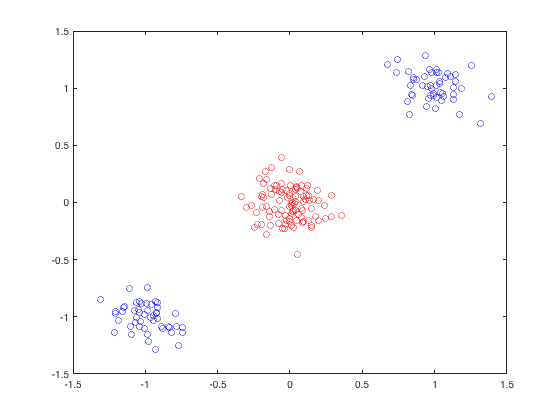

% Plotting

clf
%subplot(1, 2, 1)
plot(blue_x1, blue_x2, 'o', Color = 'blue')
hold on
plot(blue2_x1, blue2_x2, 'o', Color = 'blue')
plot(red_x1, red_x2, 'o', Color = 'red')

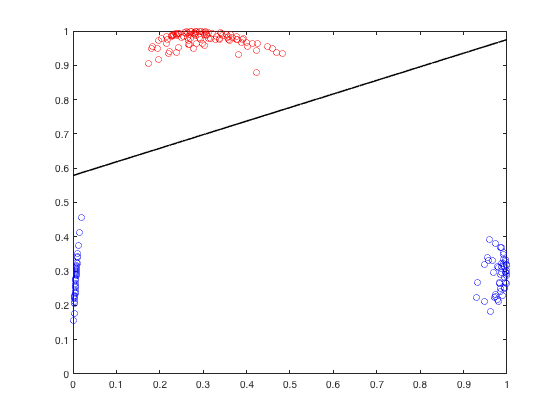

discr = @(x1, x2) w(1) + w(2)*x1 + w(3)*x2;

clf
h2 = fimplicit(discr, [0 1 0 1]);
h2.Color = 'black';
h2.LineWidth = 1.5;
hold on

plot(blue1_transformed(:, 1), blue1_transformed(:, 2), 'o', Color = 'blue');
plot(blue2_transformed(:, 1), blue2_transformed(:, 2), 'o', Color = 'blue');
plot(red_transformed(:, 1), red_transformed(:, 2), 'o', Color = 'red');

(Unfortunately I did not have time to discover the inverse transformation for the two gaussian basis functions in order to map the discriminant back to the input space.)

## Helper Functions

function v = neglog_likelihood(w, x, y)
% Negative Log Likelihood computation for weights where x is a N x 3 matrix
% and desired discriminant is linear
v = 0;
for i = 1:length(x)
    x1 = x(i, 1);
    x2 = x(i, 2);
    x3 = x(i, 3);
    s = w(1) + w(2)*x1 + w(3) * x2 + w(4)*x3;
    if y(i) == 1
        v = v + log(1+exp(-s));
    else
        v = v + log(1 + exp(s));
    end
end
end

function v = neglog_likelihood_quad(w, x, y)
% Negative Log Likelihood computation for weights where x is a N x 3 matrix
% and desired discriminant is quadratic
v = 0;
for i = 1:length(x)
    x1 = x(i, 1);
    x2 = x(i, 2);
    x3 = x(i, 3);
    s = w(1) + w(2)*x1 + w(3)*x2 + w(4)*x3 + w(5)*x1*x1 + w(6)*x1*x2 + w(7)*x1*x3 + w(8)*x2*x3 + w(9)*x2*x2 + w(10)*x3*x3;
    if y(i) == 1
        v = v + log(1+exp(-s));
    else
        v = v + log(1 + exp(s));
    end
end
end

% Returns a N x 2 matrix where col1 = phi1(x_vec), col2 = phi2(x_vec)
function Phi = gaussian_basis(x1, x2)
    xvec = [x1 x2];
    s = 0.9;
    mu1 = [-1 -1];
    mu2 = [0 0];
    Phi = zeros(length(xvec), 2);
    for i = 1:length(x1)
        Phi(i, 1) = exp(-0.5/(s^2) * norm(xvec(i, :) - mu1)^2);
        Phi(i, 2) = exp(-0.5/(s^2) * norm(xvec(i, :) - mu2)^2);
    end
end

function v = neglog_likelihood2(w, x, y)
% Negative Log Likelihood computation for weights where x is a N x 2 matrix
% and desired discriminant is linear
v = 0;
for i = 1:length(x)
    x1 = x(i, 1);
    x2 = x(i, 2);
    s = w(1) + w(2)*x1 + w(3)*x2;
    if y(i) == 1
        v = v + log(1+exp(-s));
    else
        v = v + log(1 + exp(s));
    end
end
end